# SGP4 overview

## Initialization

clc; clear all; cspice_kclear; close all

% Replace the path below with your own installation path if not present as
% a subfolder
addpath('sgp4');

% Constant for arcseconds to radians conversions
arcsec2rad = pi / (180*3600);

We then define some parameters that are needed to initialize SGP4:

- `typerun` is just a parameter to select user-provided inputs

- `opsmode` shall be always set to `a`

- `whichconst` selects the geodetic standard (see [World Geodetic System](https://en.wikipedia.org/wiki/World_Geodetic_System)). For SGP4 it shall be version `72`.

typerun    = 'u';  % user-provided inputs to SGP4 Matlab function
opsmode    = 'a';  % afspc approach ('air force space command')
whichconst =  72;  % WGS72 constants (radius, gravitational parameter)

We are going to use SPICE for most of the transformation, so we load some kernels:

% Load spice kernels
cspice_furnsh('lab03_SPG4_overview.tm');

## Calling SGP4

We need first to define the TLE. We do this per row, defining two variables:

longstr1 = '1 00900U 64063C   21273.19997337  .00000317  00000-0  32931-3 0  9993';
longstr2 = '2 00900  90.1690  36.2462 0029114  86.7623 345.0603 13.73591954834933';

By recalling the definition of each field, we can write the mean elements associated to this TLE:

The function `twoline2rv` converts the TLE lines to "satrec" structures, that can be used by SGP4:

% initialize the satrec structure, using the function twoline2rv
satrec = twoline2rv(longstr1, longstr2, typerun,'e', opsmode, whichconst)

satrec = struct with fields:
             error: 0
            satnum: 900
    classification: 'U'
          intldesg: '64063C_ '
           epochyr: 21
         epochdays: 273.2000
              ndot: 9.6054e-12
             nddot: 0
             bstar: 3.2931e-04
             elnum: 999
             inclo: 1.5737
             nodeo: 0.6326
              ecco: 0.0029
             argpo: 1.5143
                mo: 6.0224
          no_kozai: 0.0599
            revnum: 83493
        jdsatepoch: 2.4595e+06
       jdsatepochf: 0.2000
             isimp: 0
            method: 'n'
             aycof: 0.0012
             con41: -1.0000
               cc1: 1.0363e-10
               cc4: 1.8575e-08
               cc5: 1.0714e-05
                d2: 3.4918e-19
                d3: 1.7527e-27
                d4: 1.0248e-35
             delmo: 1.0702
               eta: 0.0237
           argpdot: -3.6457e-05
            omgcof: 5.8510e-11
            sinmao: -0.2578
                 t: 0
          

The TLE reference epoch is recorded inside the `jdsatepoch` and `jdsatepochf` fields (JD = jdsatepoch + jdsatepochf).

The `invjday` function converts `jdsatepoch` and `jdsatepochf` to year, month, day, hour, minutes and seconds.

Year, month, day, hour, minutes and seconds are converted to strings, then to ET time by `cspice_str2et`.

% Get TLE epoch
[year,mon,day,hr,min,sec] = invjday(satrec.jdsatepoch, satrec.jdsatepochf);
sat_epoch_str = sprintf('%d-%02d-%02dT%02d:%02d:%02.6f', [year,mon,day,hr,min,sec]);
sat_epoch_et = cspice_str2et(sat_epoch_str);

fprintf('Satellite num ID: %d\n', satrec.satnum);

Satellite num ID: 900


fprintf('TLE reference epoch: UTC %s', sat_epoch_str);

TLE reference epoch: UTC 2021-09-30T04:47:57.699168

Once the satellite record is initialized, we can simply call the function `sgp4` providing as an additional input the time in minutes from the TLE epoch (negative values means that evaluation time is before the TLE epoch, positive values that is after).

% Evaluate the TLE at its reference epoch
[satrec,rteme,vteme] = sgp4(satrec,  0.0);

Once we compute the TEME state vectors, we can use SPICE routines to get the osculating elements:

% Get the osculating orbital elements
% the osculating orbit of an object in space at a given moment in time is the 
% gravitational Kepler orbit that it would have around its central body if
% perturbations were absent. That is, it is the orbit that coincides with
% the current orbital state vectors.

elts = cspice_oscelt( [rteme;vteme], sat_epoch_et, satrec.mu );

fprintf('*** Osculating orbital elements ***')

*** Osculating orbital elements ***

fprintf('SMA   [km]:  %.5f', elts(1)/(1-elts(2)));

SMA   [km]:  7354.62819

fprintf('ECC   [km]:  %.8f', elts(2));

ECC   [km]:  0.00269575

fprintf('INC  [deg]: %.5f', elts(3)*cspice_dpr());

INC  [deg]: 90.16908

fprintf('RAAN [deg]: %.5f', elts(4)*cspice_dpr());

RAAN [deg]: 36.24614

fprintf('ARGP [deg]: %.5f', elts(5)*cspice_dpr());

ARGP [deg]: 100.95290

fprintf('M.AN [deg]: %.5f', elts(6)*cspice_dpr());

M.AN [deg]: 330.90096

fprintf('LONP [deg]: %.5f', (rem(elts(5)+elts(6), 2*pi))*cspice_dpr())

LONP [deg]: 71.85385

We can observe that these are different from the mean values defined in the TLE: the periodic effects have been added.

## TEME-ECI conversions

To convert the TEME state vector to inertial frame J2000 (which in this case is equivalent to Earth Centered Intertial, ECI) we need:

- the coefficients dPsi and dEpsilon to apply nutation corrections

- the time in centuries from TDT 2000 January 1 00:00:00.000 to compute, using a polynomial approximation, the precession correction

For the first, we use SPICE time conversion routines, more specifically the `cspice_unitim`. The function `cspice_jyear` returns instead the number of seconds per julian year and we exploit it for the conversion.

% Centuries from TDT 2000 January 1 00:00:00.000
et0 = cspice_str2et('2004-04-06T07:51:28.386009');
ttt = cspice_unitim(et0, 'ET', 'TDT')/cspice_jyear()/100;   % Performs time conversion into seconds
                                                            % and then
                                                            % divide to get
                                                            % # of
                                                            % centuries

For the dPsi andd dEpsilon correction for the nutation: these are taken from the Earth-Orientation-Parameter file, which is also available from the CelesTrack website, under [EOP data](https://celestrak.com/SpaceData/EOP-Last5Years.txt)

We can look for the line corresponding to the TLE epoch (in this case it corresponds to the date) and get the delta-Psi and delta-Epsilon corrections. We then need to convert them from arcsec to radians

ddpsi = -0.117144*arcsec2rad; %  [rad]
ddeps = -0.009050*arcsec2rad; %  [rad]

At this point we are ready to call the function to convert from TEME to ECI. Since we do not have an acceleration, we just give a dummy vector of zeros.

% ---------------------- eci transformations ----------------------
% -------- teme2eci    - transform teme to eci vectors
ateme = [0;0;0];
fprintf(1,'\n\n start from teme \n');



 start from teme 


[reci, veci, aeci] = teme2eci(rteme, vteme, ateme, ttt, ddpsi, ddeps);
fprintf(1,'teme-eci\n reci %14.7f %14.7f %14.7f',reci );

teme-eci
 reci   1873.8725450   1343.8249471   6965.5551449

fprintf(1,' veci %14.9f %14.9f %14.9f\n',veci );

 veci   -5.651831831   -4.144247520    2.309766454


fprintf(1,' aeci %14.9f %14.9f %14.9f\n',aeci );

 aeci    0.000000000    0.000000000    0.000000000


Finally, we convert the vectors back to TEME:

% -------- eci2teme    - transform eci to teme vectors
[rteme1, vteme1] = eci2teme(reci, veci, aeci, ttt, ddpsi, ddeps);
fprintf(1,'ecef-teme\n rteme %14.7f %14.7f %14.7f',rteme1 );

ecef-teme
 rteme   1869.8722352   1345.3623367   6966.3333460

fprintf(1,' vteme %14.9f %14.9f %14.9f\n',vteme1 );

 vteme   -5.648780177   -4.149714855    2.307414302


dr = 1000*(rteme - rteme1);  % in m

and to conclude we check that we obtain the same starting values:

fprintf(1,'diff in teme %14.7f %14.7f %14.7f %14.7f \n',dr,mag(dr) );

diff in teme      0.0000000     -0.0000000      0.0000000      0.0000000 


## SGP4 difference

This example wants to show the errors between two consecutive TLEs, by evaluating them on the same time span.

We take two TLE from the archive with approximately one day difference between the reference epochs:

We then load the TLEs and initialize the input structures:

% Load TLE for satellite ERS-1
longstr1 = '1 21574U 91050A   04365.75303333  .00000022  00000-0  22335-4 0  1657';
longstr2 = '2 21574  98.3621  66.8650 0033402 268.4180  91.3179 14.35473805704306';

satrec_old = twoline2rv(longstr1, longstr2, typerun,'e', opsmode, whichconst);

[year,mon,day,hr,min,sec] = invjday(satrec_old.jdsatepoch, satrec_old.jdsatepochf);
old_tle_epoch_str = sprintf('%d-%02d-%02dT%02d:%02d:%02.6f', [year,mon,day,hr,min,sec]);
old_sat_epoch_et = cspice_str2et(old_tle_epoch_str);



% Load following TLE for satellite ERS-1
longstr1 = '1 21574U 91050A   04366.65918085  .00000022  00000-0  22295-4 0  1658';
longstr2 = '2 21574  98.3618  67.7444 0033269 265.5469  94.1930 14.35474163704430';

satrec_new = twoline2rv(longstr1, longstr2, typerun,'e', opsmode, whichconst);

[year,mon,day,hr,min,sec] = invjday(satrec_new.jdsatepoch, satrec_new.jdsatepochf);
new_tle_epoch_str = sprintf('%d-%02d-%02dT%02d:%02d:%02.6f', [year,mon,day,hr,min,sec]);
new_sat_epoch_et = cspice_str2et(new_tle_epoch_str);

fprintf('Satellite num ID: %d\n', satrec_new.satnum);

Satellite num ID: 21574


fprintf('Old TLE reference epoch: UTC %s', old_tle_epoch_str);

Old TLE reference epoch: UTC 2004-12-30T18:04:22.079712

fprintf('New TLE reference epoch: UTC %s', new_tle_epoch_str);

New TLE reference epoch: UTC 2004-12-31T15:49:13.225440

We then prepare for the comparison:

% Start of comparison: two (5?) days before old TLE reference epoch
et0 = old_sat_epoch_et - 5.0*cspice_spd();

% End of comparison: two (5?) days after new TLE reference epoch
etf = new_sat_epoch_et + 5.0*cspice_spd();

% Equally space vector, with one minute time-step
npoints = round((etf-et0)/60.0)+1;
et_vec = linspace(et0, etf, npoints);

% initialize error vector
diff_pos = zeros(3, npoints);
diff_vel = zeros(3, npoints);

for i = 1:npoints

    tsince_old = (et_vec(i) - old_sat_epoch_et)/60.0;
    [~,rteme_old,vteme_old] = sgp4(satrec_old,  tsince_old);


    tsince_new = (et_vec(i) - new_sat_epoch_et)/60.0;
    [~,rteme_new,vteme_new] = sgp4(satrec_new,  tsince_new);

    diff_pos(:,i) = rteme_new - rteme_old;
    diff_vel(:,i) = vteme_new - vteme_old;

end

### Plots

We now plot the difference in position for each component and the magnitude of the difference:

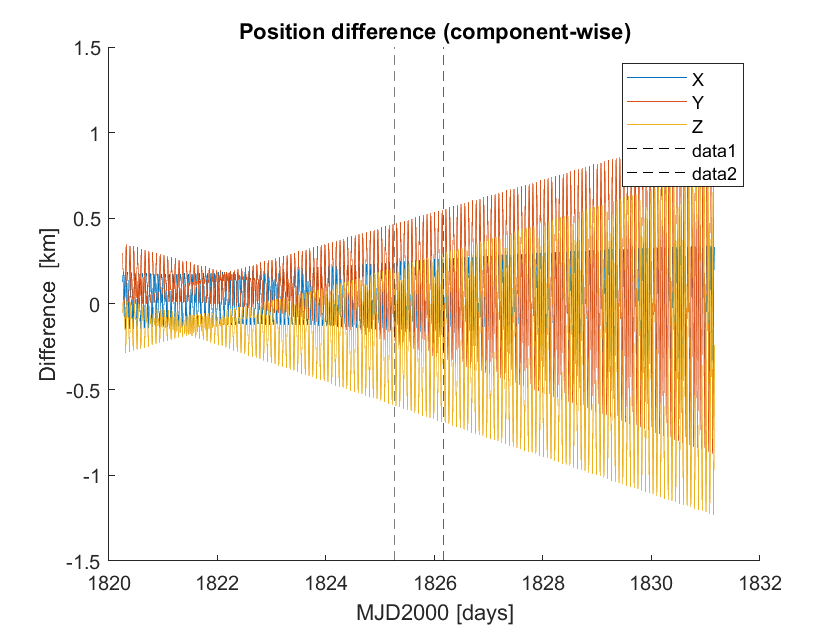

figure(1)
clf, hold on
plot(et_vec/cspice_spd(), diff_pos)
xlabel('MJD2000 [days]')
ylabel('Difference  [km]')
legend({'X','Y','Z'})
title('Position difference (component-wise)')
ax = axis;
plot([old_sat_epoch_et/cspice_spd(), old_sat_epoch_et/cspice_spd()], [ax(3), ax(4)],'k--');
plot([new_sat_epoch_et/cspice_spd(), new_sat_epoch_et/cspice_spd()], [ax(3), ax(4)],'k--');

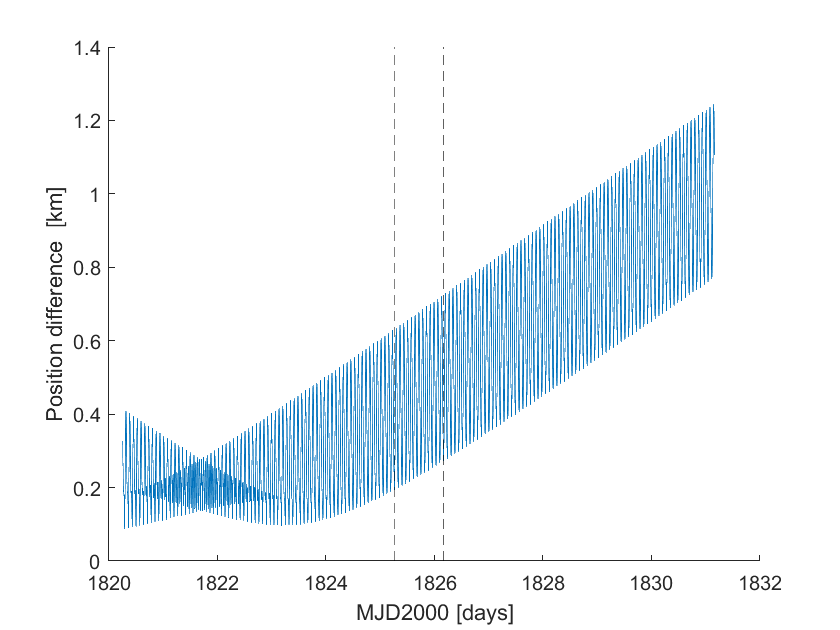


figure(2)
clf, hold on
plot(et_vec/86400.0, vecnorm(diff_pos,2,1))
xlabel('MJD2000 [days]')
ylabel('Position difference  [km]')
ax = axis;
plot([old_sat_epoch_et/cspice_spd(), old_sat_epoch_et/cspice_spd()], [ax(3), ax(4)],'k--');
plot([new_sat_epoch_et/cspice_spd(), new_sat_epoch_et/cspice_spd()], [ax(3), ax(4)],'k--');

## Antenna pointing

As a last excercise we try to compute the antenna pointings (azimuth, elevation) and range and range-rate values:

% Define station name (inspect estrack_3v.tf to find list of stations)
stationName = 'KIRUNA1';
spacecraftName = 'Sentinel-3A';
spacecraftID = 41335;

% Extract the TLE from a 3LE file and initialize the inputs for SGP4
% Sentinel-3A
sent3a = read_3LE(spacecraftID, 'tle\active.tle', whichconst);

% Get TLE epoch
[year,mon,day,hr,min,sec] = invjday(sent3a.jdsatepoch, sent3a.jdsatepochf);
s3a_epoch_str = sprintf('%d-%02d-%02dT%02d:%02d:%02.6f', [year,mon,day,hr,min,sec]);
s3a_epoch_et = cspice_str2et(s3a_epoch_str);

fprintf('Satellite num ID: %d\n', sent3a.satnum);

Satellite num ID: 41335


fprintf('TLE reference epoch: UTC %s', s3a_epoch_str);

TLE reference epoch: UTC 2021-09-30T03:49:21.467136

Let's compute a set of state vector with SGP4 and convert them from TEME to ECI (J2000) to perform computations with SPICE:

% Set initial and final states
et0 = s3a_epoch_et - 0.5*cspice_spd();
etf = s3a_epoch_et + 0.5*cspice_spd();

% Equally space vector, with one minute time-step
npoints = round((etf-et0)/60.0)+1;
et_vec = linspace(et0, etf, npoints);

% Set nutation corrections parameters (same date as first example -> same values)
ddpsi = -0.117144*arcsec2rad; %  [rad]
ddeps = -0.009050*arcsec2rad; %  [rad]

% Loop over epochs
reci_s3a = zeros(3,npoints);
veci_s3a = zeros(3,npoints);

for i = 1:npoints

    tsince = (et_vec(i) - s3a_epoch_et)/60.0; % minutes from TLE epoch
    [~,rteme_s3a,vteme_s3a] = sgp4(sent3a,  tsince);

    % Compute centuries from 2000-01-01T00:00:00.00 TDT
    ttt = cspice_unitim(et_vec(i), 'ET', 'TDT')/cspice_jyear()/100;

    [reci_s3a(:,i), veci_s3a(:,i)] = ...
        teme2eci(rteme_s3a, vteme_s3a, [0.0;0.0;0.0],  ttt, ddpsi, ddeps);

end

### **Excercise:**

Transform the ECI position into Earth fixed frame (use IAU_EARTH), then plot the orbit in this new reference frame.

### Plots

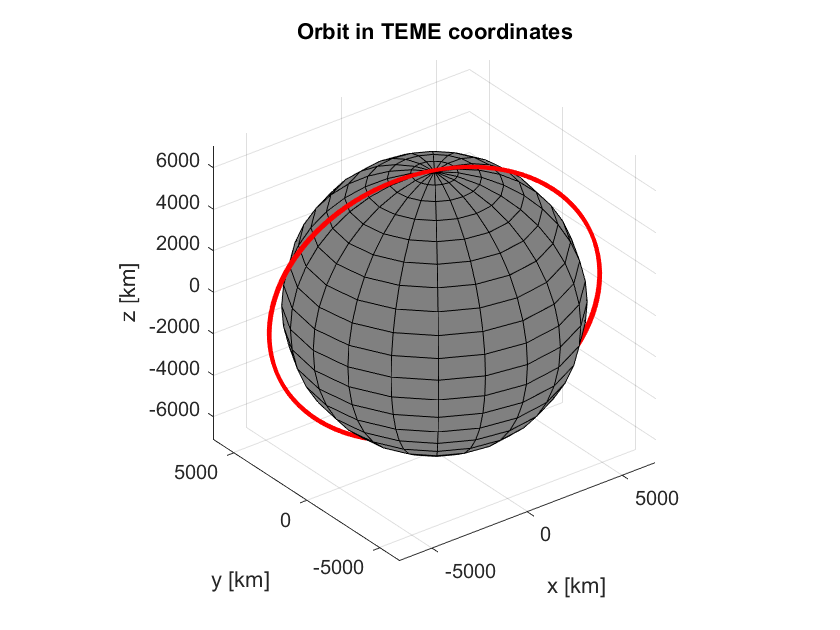

figure(3);
% Plot Earth
[X, Y, Z] = sphere;
EarthRadius = cspice_bodvrd('EARTH','RADII',3);
hSurface = surf(X*EarthRadius(1), Y*EarthRadius(1), Z*EarthRadius(1));
set(hSurface,'FaceColor',[0.5 0.5 0.5])
hold on; grid on; axis equal;

% Plot positions of A and B
plot3(reci_s3a(1, :), reci_s3a(2, :), reci_s3a(3, :), 'r', 'DisplayName', 'Sentinel 3A','LineWidth',2);
title('Orbit in TEME coordinates');
xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');

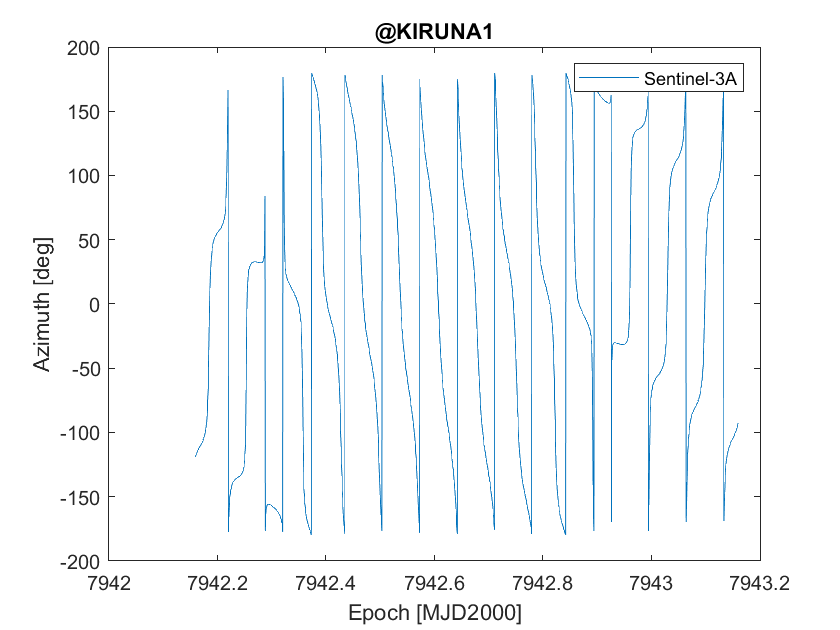


% Compute antenna angles, satellite range and range-rate
[s3a_azimuth, s3a_elevation, s3a_range, s3a_range_rate] = ...
    antenna_pointing(stationName, et_vec, [reci_s3a;veci_s3a]);

figure(4)
plot(et_vec/cspice_spd(), s3a_azimuth*cspice_dpr(), 'DisplayName', spacecraftName)
title(['@',stationName])
xlabel('Epoch [MJD2000]')
ylabel('Azimuth [deg]')
legend(spacecraftName)

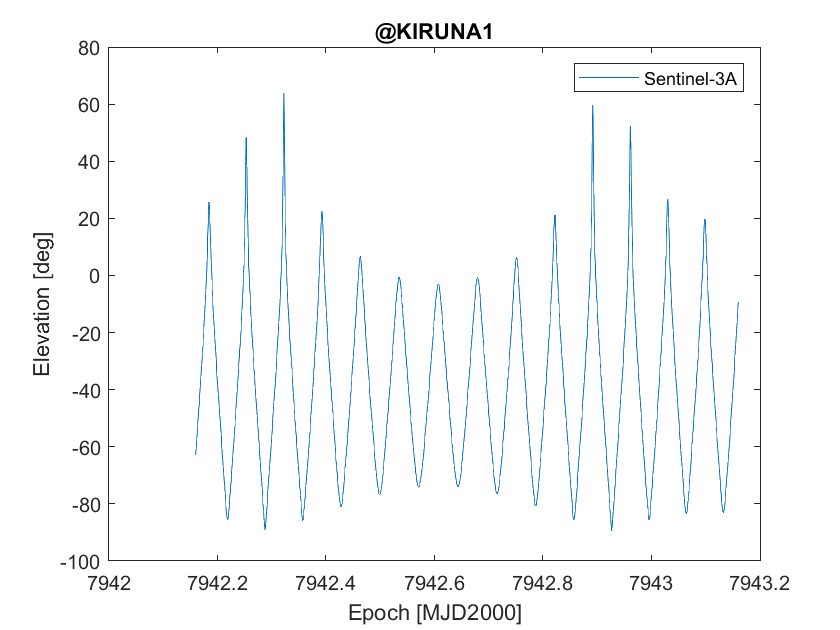


figure(5)
plot(et_vec/cspice_spd(), s3a_elevation*cspice_dpr(),'DisplayName', spacecraftName)
title(['@',stationName])
xlabel('Epoch [MJD2000]')
ylabel('Elevation [deg]')
legend(spacecraftName)

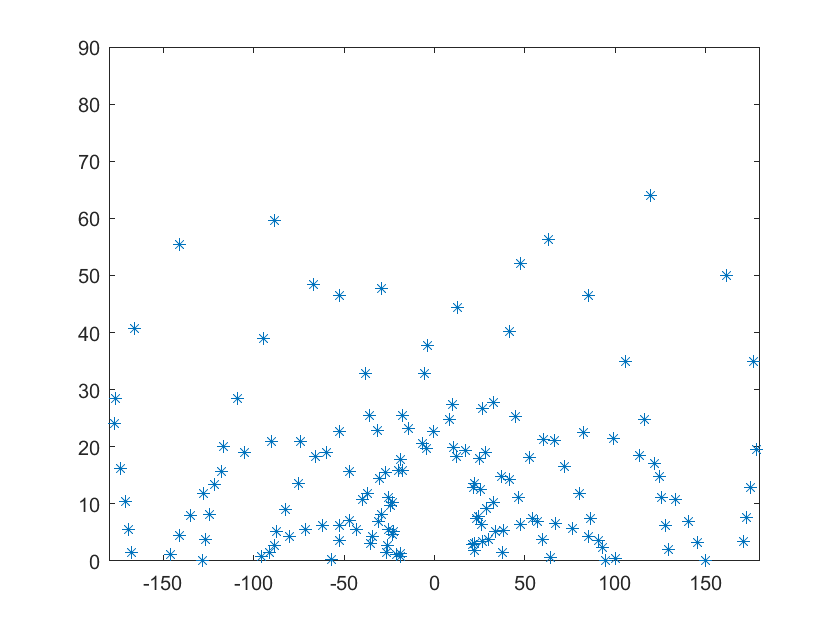


% Plot passes (azimuth and elevation)
figure(6)
i_visibility = s3a_elevation > 0;
plot(s3a_azimuth(i_visibility)*cspice_dpr(), s3a_elevation(i_visibility)*cspice_dpr(),'*','DisplayName', spacecraftName)
axis([-180,180,0, 90])

## Kernel cleanup

% clean kernel pool
cspice_kclear();